load('energyStructures.mat');

close all

% Define colors and structure names
colors = {'#0072BD', '#D95319', '#7E2F8E'};  % Blue, Red, Purple
structs = {imExp, imPAPA, imAgu};
labels = {'Exp', 'PAPA', 'Agu'};
components = {'HKE', 'VKE', 'PE'};
titles = {'Horizontal Velocity', 'Vertical Velocity', 'Isopycnal'};
z1 = -500;

% Pré-calcular energia e frequência para cada estrutura e componente
freqCPD = cell(1, 3); % Frequências por estrutura
energyData = cell(3, 3); % energyData{i, j} = componente i, estrutura j

for j = 1:3  % estruturas
    freqCPD{j} = (structs{j}.omegaVector)*(24*3600)/(2*pi); % converter rad/s para cpd
    for i = 1:3  % componentes
        energyData{i, j} = structs{j}.energyAtFrequencies(z1, components{i}, plot=0);
    end
end

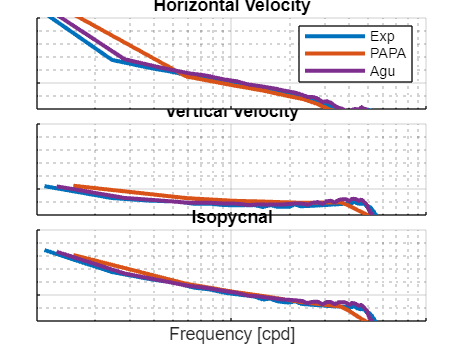

close all
% Plotar
figure(4)
[ha, pos] = tight_subplot(3,1,[0.04 0.04], [0.07 0.05], [0.08 0.07]);

for i = 1:3
    axes(ha(i));
    hold on
    for j = 1:3
        loglog(freqCPD{j}, energyData{i,j} * 1000, 'LineWidth', 2, 'Color', colors{j});
    end
    grid on
    ylim([1e-7 1e0])
    set(gca, 'XScale', 'log');
    set(gca, 'YScale', 'log');
    if i < 3
        xticklabels([]);
    else
        xlabel('Frequency [cpd]');
    end
    title(titles{i});
end

axes(ha(1));
legend(labels);


% (Opcional) salvar estruturas
%save('energyStructures.mat', 'imExp', 'imPAPA', 'imAgu');

% Save the figure  
filename = sprintf('FrequencyPowerSpectrum_Kindof_WRONG.png');
%filename = sprintf('FrequencyPowerSpectrum_%s.png', stationName);  
set(gcf, 'Position', [80, 100, 350, 700]); 
pause(0.1);
print(filename, '-dpng', '-r300');

close all
im = imAgu;  

zvect2 = [-100, -300, -500, -1000, -1500];
legendDepth=["100 m","300 m","500 m","1000 m","1500 m"]

legendDepth = 1×5 string array
    "100 m"    "300 m"    "500 m"    "1000 m"    "1500 m"


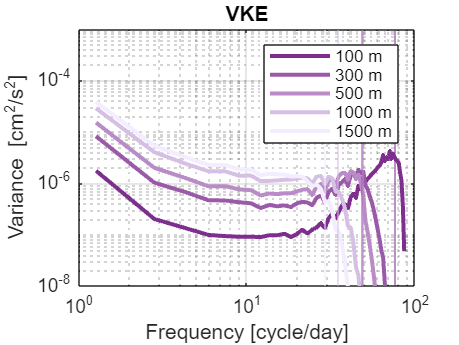

% Orange
%colors = ["#D95319", "#E3753F", "#ED9266", "#F5AF8C", "#FBDCC0"];

% Blue
%colors = ["#0072BD", "#338CCC", "#66A6DA", "#99C1E8", "#CCE4F5"];

%Purple
colors = ["#7E2F8E", "#9B59AA", "#B98CC7", "#D6BFE4", "#F3EDFF"];



clf
for i = 1:length(zvect2)

        [S,~]=im.energyAtFrequencies(zvect2(i),'VKE', plot=0);
        loglog((im.omegaVector)*(24*3600)/(2*pi), S*1000,Color=colors(i),LineWidth=2) 
        hold on        
end

legend(legendDepth, 'Location', 'best');
ylim([10^-8,10^-3])

for i = 1:length(zvect2)
        xline((sqrt(im.N2(zvect2(i)))*24*3600)/(2*pi),"Color",colors(i),'HandleVisibility', 'off');
        title('VKE')
        ylabel("Variance [cm^2/s^2]")
        xlabel("Frequency [cycle/day]")
        grid on
end

% Save the figure  
filename = sprintf('FrequencySpectrumDepth_Agu.png');

%set(gcf, 'Position', [80, 100, 350, 700]); 

print(filename, '-dpng', '-r300');